# ML preprocessing

clear all

labels_s1=categorical({'Mean std pressure left right', 'Mean mean pressure left right', 'Mean std accel left right', 'Mean mean accel left right', 'Median fore back ratio left',  'Median fore back ratio right', 'Median pressure heel left' , 'Median pressure midfoot left' ,'Median pressure toes left', ...
    'Median pressure heel right' , 'Median ffbf_r_a_t_i_or' , 'Median pressure toes right',  'Median pressure left' , 'Median pressure right' ,  'Median resulting accel left', 'Median resulting accel right', 'Median Accel Left z' , 'Median Accel left y', 'Median accel left x', 'Median accel right z', ...
    'Median accel right y' ,  'Median accel right x', 'Mean fore back ratio left', 'Mean fore back ratio right' , 'Mean pressure heel left', 'Mean pressure midfoot left' ,'Mean pressure toes left',   'Mean pressure heel right',   'Mean pressure midfoot right',   'Mean pressure toes right', ...
    'Mean pressure left', 'Mean pressure right', 'Mean resulting accel left', 'Mean Arr', 'Mean accel left z', 'Mean accel left y', 'Mean accel left x', 'Mean Azr', 'Mean accel right y', 'Mean Axr', 'Std. ffbf_r_a_t_i_ol', 'Std fore back ratio right', ...
    'Std pressure heel left', 'Std pressure midfoot left', 'Std. Ptl', 'Std. Phr', 'Std pressure midfoot right',   'Std pressure toes right',   'Std pressure left',   'Std pressure right',   'Std resulting accel left',   'Std. Arr', 'Std accel left z', ...
    'Std. Ayl', 'Std accel left x', 'Std accel right z', 'Std accel right y', 'Std accel right x', 'Min fore back ratio left', 'Min fore back ratio right', 'Min pressure heel left', 'Min pressure midfoot left', 'Minimum Ptl',   'Min pressure heel right', ...
    'Min pressure midfoot right', 'Min pressure toes right', 'Min pressure left', 'Min Psr', 'Minimum Arl', 'Min resulting accel right',   'Min accel left z',   'Min accel left y',   'Min accel left x', 'Min accel right z', 'Minimum Ayr', 'Min accel right x', ...
    'Max fore back ratio left', 'Max fore back ratio right', 'Max pressure heel left',  'Max pressure midfoot left', 'Max pressure toes left', 'Max pressure heel right', 'Maximum Pmr', 'Max pressure toes right', 'Max pressure left', 'Max pressure right', ...
    'Max resulting accel left', 'Max resulting accel right', 'Max accel left z', 'Max accel left y', 'Max accel left x', 'Maximum Azr', 'Max accel right y', 'Maximum Axr'});

labels_IMU=["Max accel right x",  "Max accel right y",  "Maximum Azr",  "Max accel left x",  "Max accel left y",  "Max accel left z",  "Max resulting accel right",  "Maximumg Arl",  "Min accel right x",  "Min accel right y", "Min accel right z", "Min accel left x", "Minimum Ayl",...
    "Min accel left z", "Minimum Arr", "Minimum Arl", "Std. Azr", "Std. Ayr",  "Std. Azr", "Std. Axl",  "Std. Ayl",  "Std. Azl",  "Std resulting accel right",  "Std resulting accel left",  "Mean accel right x",  "Mean accel right y", ...
    "Mean accel right z",  "Mean accel left x",  "Mean accel left y",  "Mean Azl",  "Mean resulting accel right",  "Mean resulting accel left",  "Median accel right x",  "Median accel right y",  "Median Accel Right z",  "Median Accel Left x",  "Median Accel Left y",  "Median Accel Left z",...
    "Median resulting accel right",  "Median Arl",  "Mean mean accel left right",  "Sra"]

labels_IMU = 1×42 string array
    "Max accel right x"    "Max accel right y"    "Maximum Azr"    "Max accel left x"    "Max accel left y"    "Max accel left z"    "Max resulting accel right"    "Maximumg Arl"    "Min accel right x"    "Min accel right y"    "Min accel right z"    "Min accel left x"    "Minimum Ayl"    "Min accel left z"    "Minimum Arr"    "Minimum Arl"    "Std. Azr"    "Std. Ayr"    "Std. Azr"    "Std. Axl"    "Std. Ayl"    "Std. Azl"    "Std resulting accel right"    "Std resulting accel left"    "Mean accel right x"    "Mean accel right y"    "Mean accel right z"    "Mean accel left x"    "Mean accel left y"    "Mean Azl"    "Mean resulting accel right"    "Mean resulting accel left"    "Median accel right x"    "Median accel right y"    "Median Accel Right z"    "Median Accel Left x"    "Median Accel Left y"    "Median Accel Left z"    "Median resulting accel right"    "Median Arl"    "Mean mean accel left right"    "Sra"


# Load feature set

load("Features_IMU_v3.0.mat");
load("Features_s1_v3.0.mat");


# Box Plots

sit=Features.Mean_Mean_Pressure_Left_right(Features.Class==1,1);
stand=Features.Mean_Mean_Pressure_Left_right(Features.Class==2,1);
walk=Features.Mean_Mean_Pressure_Left_right(Features.Class==3,1);
stairs=Features.Mean_Mean_Pressure_Left_right(Features.Class==4,1);

x = [sit;stand;walk;stairs];
g = [ones(size(sit));2*ones(size(stand)); 3*ones(size(walk)); 4*ones(size(stairs))];
boxplot(x,g)

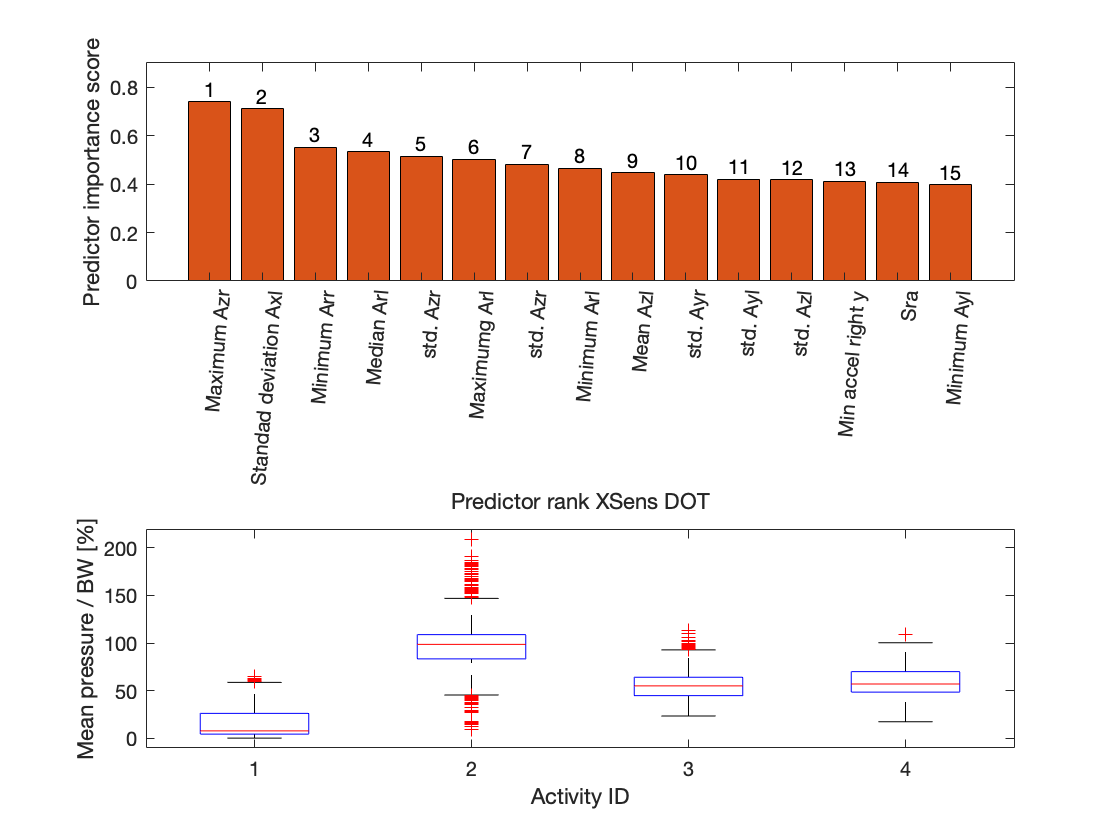


ylabel('Mean pressure / BW [%]')  
xlabel('Activity ID')  

# 2D Plots

colors=["cyan" "blue" "magenta" "black"]

colors = 1×4 string array
    "cyan"    "blue"    "magenta"    "black"


symbols=["*" "o" "x" "s"]

symbols = 1×4 string array
    "*"    "o"    "x"    "s"


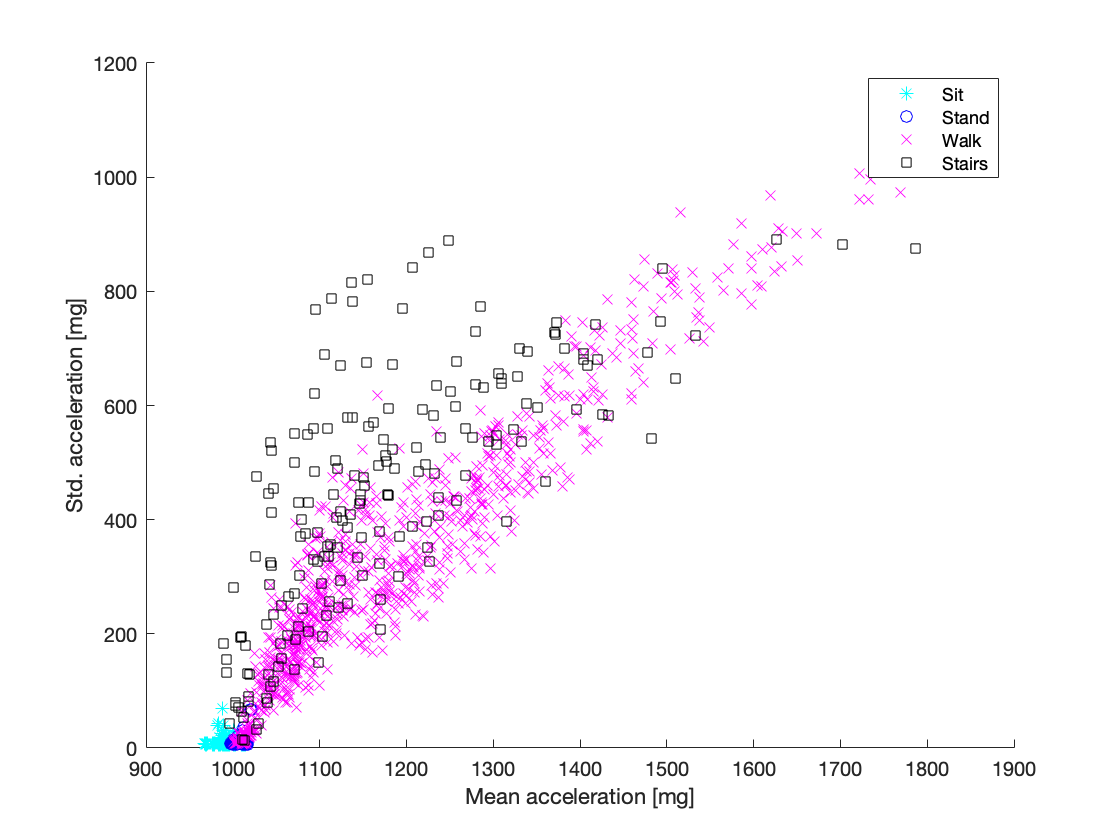


figure

hold on 
for i=1:length(colors)

scatter(Features.Mean_Mean_Accel_Left_right(Features.Class==i,1),Features.Mean_Std_Accel_Left_right(Features.Class==i,1),(symbols(i)),(colors(i)))
hold on 
end 

legend("Sit", "Stand", "Walk", "Stairs")

xlabel('Mean acceleration [mg]')   
ylabel('Std. acceleration [mg]' )

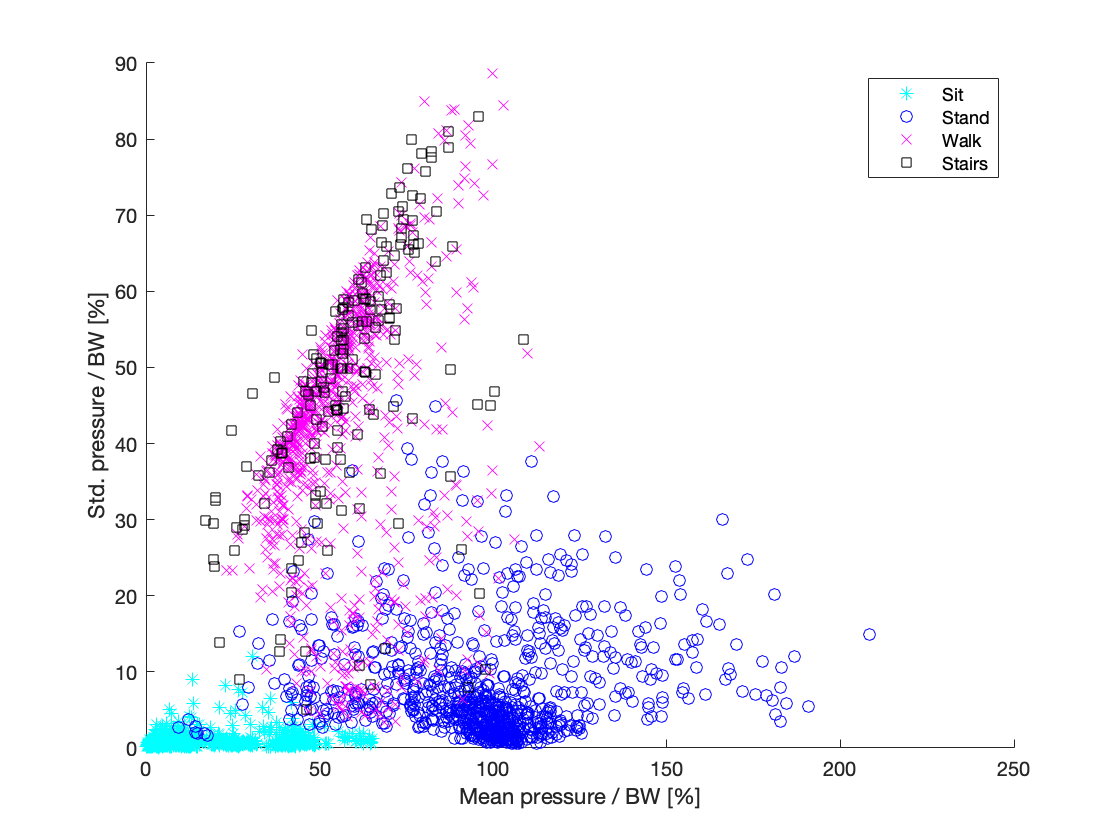

%set(gca, 'color', [0,0,1])



figure
for i=1:length(colors)

scatter(Features.Mean_Mean_Pressure_Left_right(Features.Class==i,1),Features.Mean_Std_Pressure_Left_right(Features.Class==i,1),(symbols(i)+colors(i)))
hold on 
end 

legend("Sit", "Stand", "Walk", "Stairs")

xlabel('Mean pressure / BW [%]')   
ylabel('Std. pressure / BW [%]' )


clf



# Feature Selection IMU


%%IMU




Features_table_IMU=struct2table(Features_IMU);

Features_arr_IMU=table2array(Features_table_IMU)

Features_arr_IMU =    -4.7370    2.0472    8.3938    4.7851    0.1072    8.6078    9.8688    9.8399   -4.7993    1.9957    8.3531    4.7367    0.0608    8.5563    9.8137    9.7911    0.0105    0.0094    0.0090    0.0096    0.0099    0.0103    0.0090    0.0100   -4.7695    2.0195    8.3748    4.7621    0.0844    8.5785    9.8470    9.8120   -4.7698    2.0189    8.3747    4.7625    0.0849    8.5778    9.8478    9.8113    9.8295    0.0095    1.0000    1.0000
   -4.7495    2.0466    8.4222    4.7846    0.1058    8.6033    9.8912    9.8376   -4.7919    1.9962    8.3517    4.7427    0.0541    8.5518    9.8184    9.7854    0.0090    0.0099    0.0118    0.0086    0.0094    0.0093    0.0119    0.0086   -4.7686    2.0184    8.3746    4.7608    0.0814    8.5786    9.8462    9.8114   -4.7685    2.0170    8.3737    4.7601    0.0818    8.5791    9.8462    9.8104    9.8288    0.0103    1.0000    1.0000
   -4.7378    2.0461    8.4058    4.7867    0.1057    8.6143    9.8749    9.8427   -4.7919    1.995


%%remove too detailed coma and remove Nans
for i=1:length(Features_arr_IMU)
    for j=1:42
        
        if isnan(Features_arr_IMU(i,j))==1 || isinf(Features_arr_IMU(i,j))==1
            Features_arr_IMU(i,j)=0;
        else   
            Features_arr_IMU(i,j)=round(Features_arr_IMU(i,j),4);
        end
        
    end
    
end

Features_prod_IMU=Features_arr_IMU(Features_arr_IMU(:,43)~=5,:);
Features_val_IMU=Features_arr_IMU(Features_arr_IMU(:,43)==5,:);


[idx,scores] = fscmrmr(Features_prod_IMU(:,1:42) ,Features_prod_IMU(:,43) );



%%barplot
scores_IMU=sort(scores,'descend');
labels_IMU=labels_IMU(idx)

labels_IMU = 1×42 string array
    "Maximum Azr"    "Std. Axl"    "Minimum Arr"    "Median Arl"    "Std. Azr"    "Maximumg Arl"    "Std. Azr"    "Minimum Arl"    "Mean Azl"    "Std. Ayr"    "Std. Ayl"    "Std. Azl"    "Min accel right y"    "Sra"    "Minimum Ayl"    "Max resulting accel right"    "Mean resulting accel left"    "Std resulting accel left"    "Std resulting accel right"    "Max accel left x"    "Mean resulting accel right"    "Max accel right x"    "Max accel right y"    "Median resulting accel right"    "Min accel left z"    "Mean mean accel left right"    "Mean accel right z"    "Min accel right x"    "Min accel right z"    "Min accel left x"    "Max accel left z"    "Mean accel right y"    "Median Accel Left z"    "Median Accel Left y"    "Max accel left y"    "Median Accel Right z"    "Median Accel Left x"    "Mean accel left y"    "Median accel right y"    "Median accel right x"    "Mean accel left x"    "Mean accel right x"


xtick_IMU=[2:43]

xtick_IMU =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43




b=bar(xtick_IMU,scores_IMU,'FaceColor',[0.8500 0.3250 0.0980])

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.8500 0.3250 0.0980]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43]
        YData: [1×42 double]

  Show all properties


xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels_IMU_rank = string((xtick_IMU-1));
text(xtips1,ytips1,labels_IMU_rank,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xticks(xtick_IMU)
xticklabels(labels_IMU)
xtickangle(85)

xlabel('Predictor rank')
ylabel('Predictor importance score')




Features_prod_IMU=[Features_prod_IMU(:,idx(1:42)) Features_prod_IMU(:,43:44)];




# Feature Selection S1 


Features_table=struct2table(Features);

Features_arr=table2array(Features_table);

%%remove too detailed coma and remove Nans
for i=1:length(Features_arr)
    for j=1:94
        
        if isnan(Features_arr(i,j))==1 || isinf(Features_arr(i,j))==1
            Features_arr(i,j)=0;
        else   
            Features_arr(i,j)=round(Features_arr(i,j),4);
        end
        
    end
    
end

Features_prod=Features_arr(Features_arr(:,95)~=5,:);
Features_val=Features_arr(Features_arr(:,95)==5,:);


[idx,scores] = fscmrmr(Features_prod(:,1:94) ,Features_prod(:,95) );


%%barplot
scores=sort(scores,'descend');
scores=scores(1:42)

scores =     0.8122    0.7960    0.7808    0.6648    0.6155    0.5999    0.5918    0.5497    0.5469    0.5252    0.4630    0.4514    0.4469    0.4416    0.4244    0.4188    0.4188    0.4117    0.4109    0.4081    0.4077    0.3897    0.3884    0.3873    0.3848    0.3716    0.3599    0.3572    0.3545    0.3480    0.3424    0.3382    0.3382    0.3317    0.3313    0.3230    0.3217    0.3199    0.3155    0.3155    0.3129    0.3021


labels_s1=labels_s1(idx)

labels_s1 = 1×94 categorical array
     Median ffbf_r_a_t_i_or      Mean Axr      Minimum Arl      Mean Azr      Minimum Ptl      Maximum Azr      Std. Arr      Maximum Axr      Min Psr      Std. ffbf_r_a_t_i_ol      Maximum Pmr      Mean Arr      Std. Phr      Std. Ptl      Std. Ayl      Median pressure left      Std fore back ratio right      Mean accel right y      Max resulting accel right      Mean resulting accel left      Mean accel left x      Max accel left x      Mean accel left y      Median pressure toes left      Max pressure right      Mean accel left z      Min resulting accel right      Median pressure toes right      Mean pressure right      Median pressure heel right      Std accel left z      Max pressure toes right      Std pressure right      Std accel right y      Mean pressure midfoot right      Median resulting accel left      Mean mean pressure left right      Max resulting accel left      Mean pressure toes right      Std pressure midfoot right      Mean press

xtick=[2:43]

xtick =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43


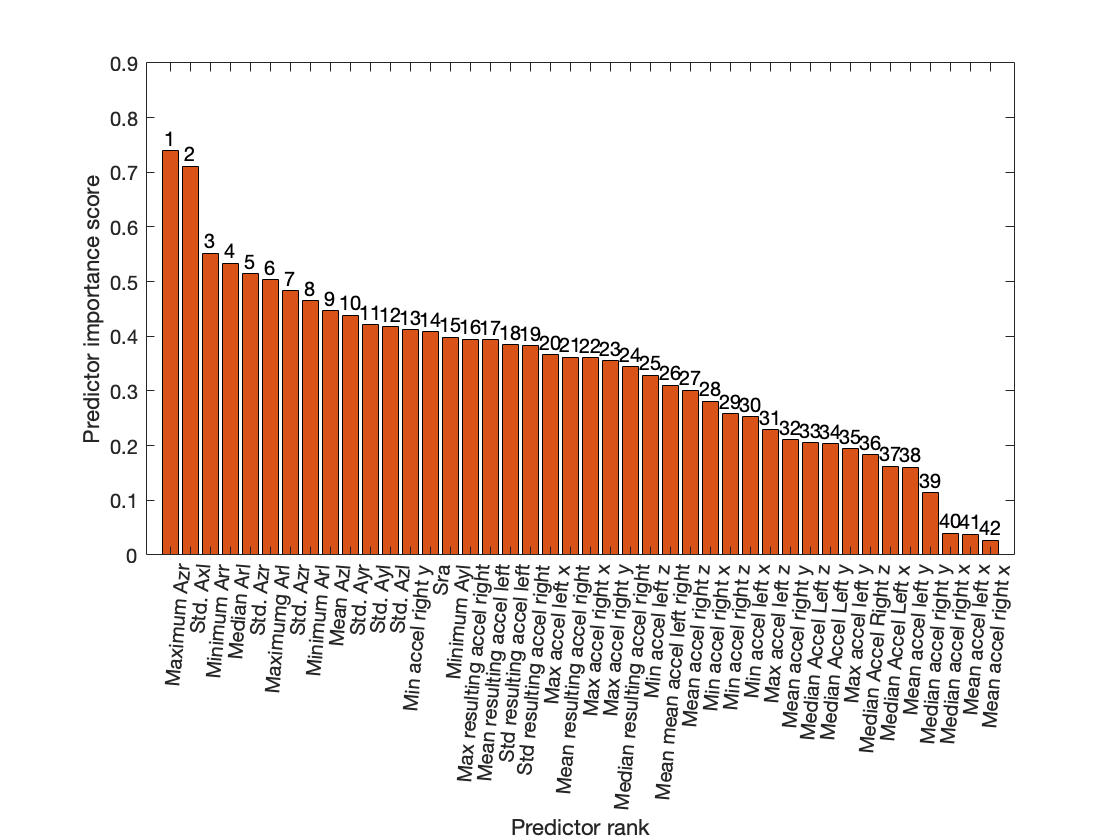

ylim([0 0.9])




b=bar(xtick,scores,'FaceColor',[0.9290 0.6940 0.1250])

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.9290 0.6940 0.1250]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43]
        YData: [1×42 double]

  Show all properties


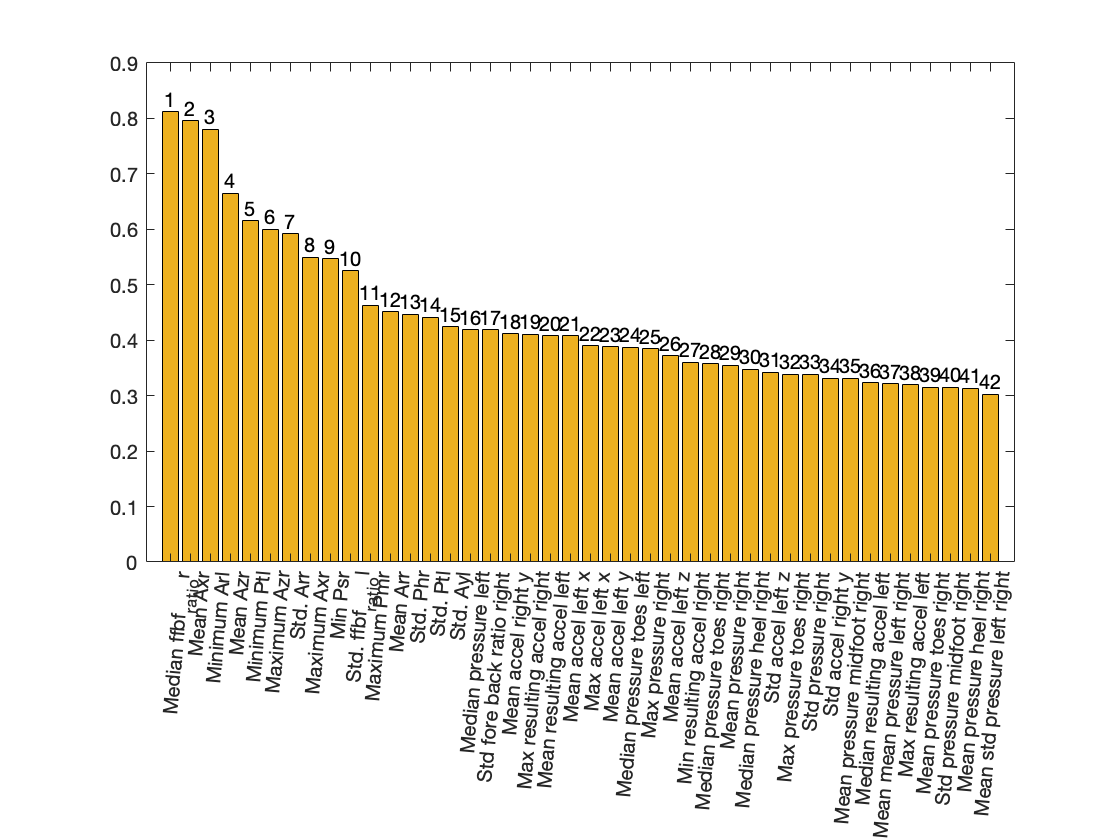

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels_s1_rank = string((xtick-1));
text(xtips1,ytips1,labels_IMU_rank,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xticks(xtick)
xticklabels(labels_s1)
xtickangle(85)


y = [1 2 3; 4 5 6];
tiledlayout(2,1)

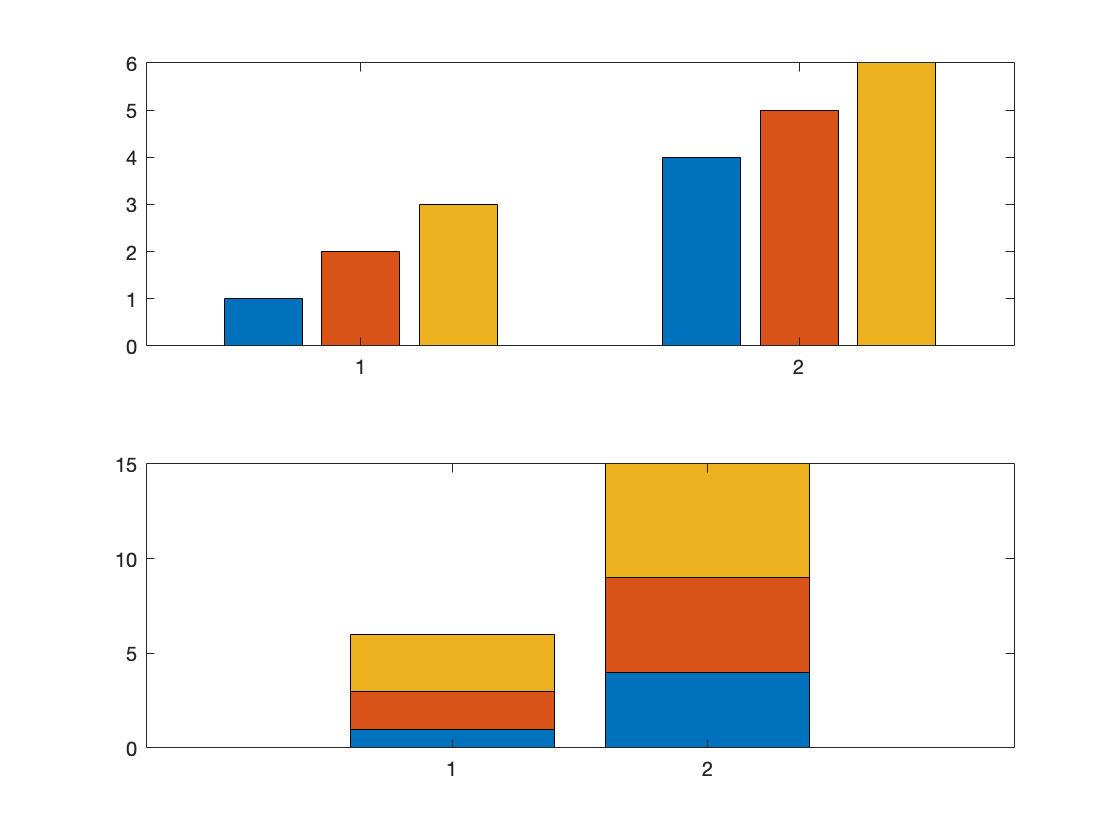


% Top bar graph
ax1 = nexttile;
bar(ax1,y)

% Bottom bar graph
ax2 = nexttile;
bar(ax2,y,'stacked')



Features_prod_s1=[Features_prod(:,idx(1:42)) Features_prod(:,95:96)];


y = [1 2 3; 4 5 6];
tiledlayout(2,1)

xtick_IMU=[2:16];
xtick=[2:16];
% Top bar graph
ax1 = nexttile;

b=bar(xtick_IMU,scores_IMU(1:15),'FaceColor',[0.8500 0.3250 0.0980])

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.8500 0.3250 0.0980]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16]
        YData: [0.7393 0.7113 0.5515 0.5334 0.5149 0.5036 0.4829 0.4651 0.4464 0.4385 0.4211 0.4176 0.4116 0.4081 0.3983]

  Show all properties


xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels_IMU_rank = string((xtick_IMU-1));
text(xtips1,ytips1,labels_IMU_rank,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xticks(xtick_IMU)
xticklabels(labels_IMU)
xtickangle(85)
ylim([0 0.9])


xlabel('Predictor rank XSens DOT')
ylabel('Predictor importance score')

% Bottom bar graph
ax2 = nexttile;

b=bar(xtick,scores(1:15),'FaceColor',[0.9290 0.6940 0.1250])

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.9290 0.6940 0.1250]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16]
        YData: [0.8122 0.7960 0.7808 0.6648 0.6155 0.5999 0.5918 0.5497 0.5469 0.5252 0.4630 0.4514 0.4469 0.4416 0.4244]

  Show all properties


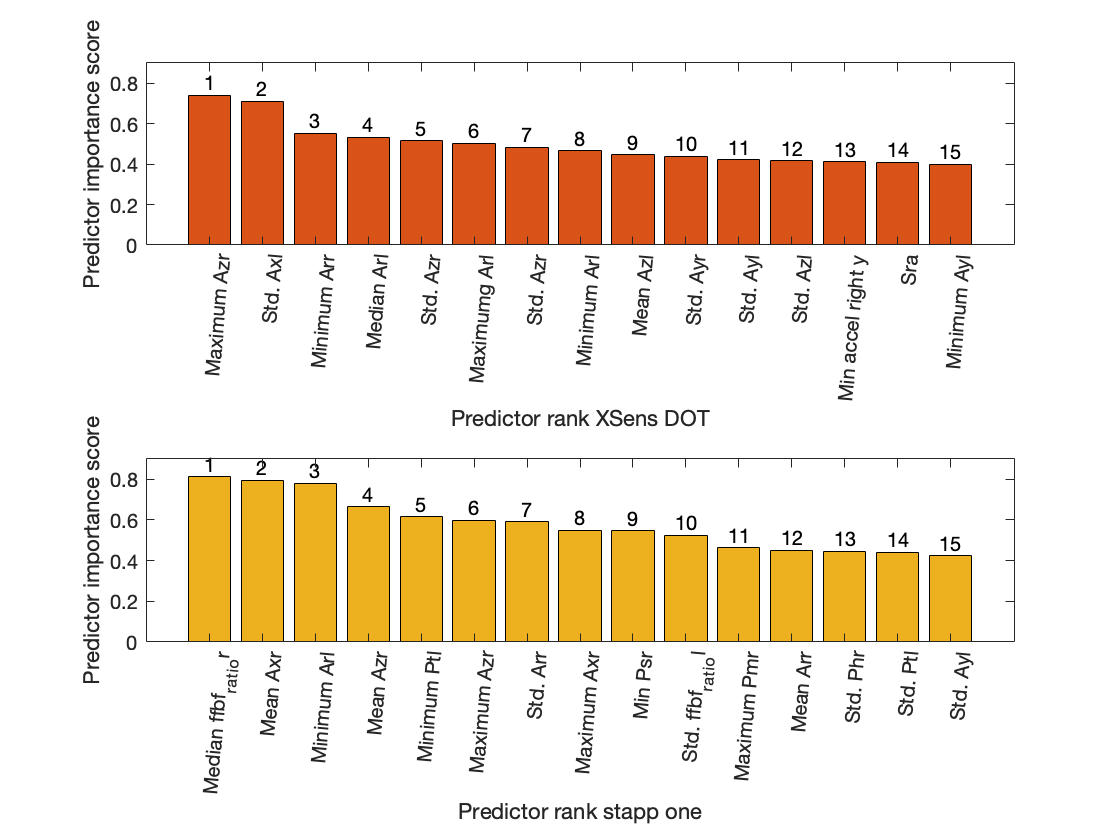

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels_s1_rank = string((xtick-1));
text(xtips1,ytips1,labels_IMU_rank,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xticks(xtick)
xticklabels(labels_s1)
xtickangle(85)
ylim([0 0.9])


xlabel('Predictor rank stapp one')
ylabel('Predictor importance score')



%Feature selection



% 
% %% feature normalization
% for i=1:8 % patient 2 until 9 (no patient 1)
% 
%     k = find(Features_prod(:,58)==i)
%    
%         
%         Features=Features_prod(k,:)
%         
%         for j=1:56
%         Features_test{i,1}(:,j)=normalize(Features(:,j)),
%         clear Features_norm
%         end
%         
%       
%         
% end
%     
% 
% finaliiii=cell2mat(Features_test) 
  


# save into csv

% 
writematrix(Features_prod_s1,'Features_prod_v3.0.csv');
% writematrix(Features_best_20,'Features_prod_v1.2_20.csv');
% writematrix(Features_best_30,'Features_prod_v1.2_30.csv');
% writematrix(Features_best_40,'Features_prod_v1.2_40.csv');
% 
% 
writematrix(Features_prod_IMU,'Features_prod_IMU_v3.0.csv');
% writematrix(Features_best_20_IMU,'Features_prod_IMU_v1.2_20.csv');
% writematrix(Features_best_30_IMU,'Features_prod_IMU_v1.2_30.csv');
% writematrix(Features_best_40_IMU,'Features_prod_IMU_v1.2_40.csv');